# Chapter 3: Taylor's Model

% Bootstrap: walk up from this file until setup_paths.m is found, then put
% the library on the path. This works whether you are running the .m source
% or the generated .mlx, from any folder.
projectDir = fileparts(mfilename('fullpath'));
while ~isfile(fullfile(projectDir, 'setup_paths.m')) && ...
        ~strcmp(projectDir, fileparts(projectDir))
    projectDir = fileparts(projectDir);
end
addpath(projectDir);
setup_paths;

## 3.1 Taylor's model and equivalent representations

We consider an extension of the linear Abelson model [M2.1](matlab:open('./ch02_abl.mlx')).

Such model involves $n$ agents with opinions $x_1, \dots, x_n \in \mathbb R$ and $m\ge 1$ communication sources, providing static opinions $s_1, \dots, s_m \in \mathbb R$. 

The agents' opinions are influenced by these sources, obeying the model 

                                                        (M3.1)$\dot x_i(t) = \sum^n_{j=1}a_{ij}(x_j(t)-x_i(t))+\sum^m_{k=1}b_{ik}(s_k-x_i(t))$

Such model involves the non-square $n\times m$ nonnegative matrix $B = (b_{ik})$ which describe the influence of the communication sources on the agents:

- $b_{i1}=\dots=b_{im}=0$ agents can be free of the external influence

- $\sum_{k=1}^mb_{ik}>0$ agents are influenced by one or several sources

This model can be considered as the Abelson model with $n+k$ agents, where "virtual" agents $n+1, \dots, n+k$ are stubborn: $x_{n+i}=s_i \text{ for } i = 1, \dots, k$ [**Corollary 2.1**](matlab:open('./ch02_abl.mlx')) imples that the model M3.1 is **convergent**: for any $x(0) \text{ and } s_1, \dots, s_k$ there exist the limit $x(\infty) = \lim_{t\rightarrow \infty}x(t)$. 

The converse is also true: for the Abelson model with $k\ge1$ stubborn agents, their static opinions may be considered as "communication sources" for the others.

Another transofrmation allows to reduce M3.1 to a formally less general model, where each agent may have its own "communicstion source" or **prejudice**

                                                                (M3.2)$\dot x_i(t) = \sum^n_{j=1}a_{ij}(x_j(t)-x_i(t))+\gamma_i(u_i-x_i(t))$

where $\gamma_i\ge0$. 

By choosing $\gamma_i \triangleq \sum_{m=1}^k b_{im}\ge0$ and $u_i \triangleq \gamma_i^{-1}\sum_{m=1}^kb_{im}s_m$ (if $\gamma_i=0$ we set $u_i=0$ w.l.o.g.)  M3.1 reduces to M3.2.

Given a group of $n$ agents, governed by the model M3.2, we call an agent $i$ **prejudiced **if $\gamma_i>0$; the extrnal inputs $u_i$ are referred to as the **prejudices **of corresponding agents.

An agent that is not prejudiced obeys the usual Abelson mechanism [M2.1](matlab:open('./ch02_abl.mlx')).

A prejudiced agent may be totally closed to the interpersonal influence $a_{ij}=0\forall j$; in this case its opinion converges to its prejudice $x_i(t)\rightarrow u_i \text{ for } t \rightarrow \infty$ and $\gamma_i$ regulates the convergence rate.

In the special case where $u_i = x_i(0)$ such an agent is stubborn since $x_i(t) \equiv u_i$.

## 3.2 Stability of the Taylor model

It is sufficient to study M3.2 since it can reduce to M3.1.

By introducing the matrix $\Gamma = diag(\gamma_1, \dots, \gamma_n)$ the model M3.2 is rewritten as

                                                                        (M3.3)$\dot x(t) = -(L[A]+\Gamma)x(t)+\Gamma u$

We split agents in two classes:

- Agent $i$ is said to be **P-dependent **(prejudice dependent, for simplicity **PD**) if is either prejudiced or influenced by some prejudiced agent $j$ (ie: a walk from $j$ to $i$ exists in the graph $\mathcal G [A]$).

- Agent i is said to be **P-independent **(for simplicity **PI**) otherwise.

Assume agents $1, \dots,r\ge 1$ are PD and agents $r+1,\dots,n$ are PI (possibly $r=n$). Denote the corresponding parts of the opinion vecotr by, respectively, $x^1(t)$ and $x^2(t)$. 

Since PD agents are not conntected to PI ones M3.3 is decomposed as

                                                            (M3.3.1)$\dot x^1(t) = -(L^{11}+\Gamma^{11})x^1(t)-L^{12}x^2(t)+\Gamma^{11}u^1$

                                                                                (M3.3.2)$\dot x^2(t) = -L^{22}x^2(t)$

The matrix $L^{22}$ is Laplacian of size $(n-r)\times(n-r)$, ie M3.3.2 is the Abelson model. The matrix $L^{11}$ is, in general, not Laplacian; one has $L^{11}\mathbb 1_r \ge 0$

**Theorem 3.1 **Let the community have $r \ge 1$ PD agents and $n-r \ge 0$ PI ones. Then the dynamics of PD agents M3.3.1 is asymptotically stable, ie the matrix $-(L^{11}+\Gamma^{11})$ is Hurwitz. The vector of their opinions converges to

                                                                                
$$x^1(\infty) = M [u^1 , x^2(\infty)]^T \\
M \triangleq (L^{11}+\Gamma^{11})^{-1}[\Gamma^{11} \ L^{12}]$$


The matrix M is stochastic, and thus the final opinion of any agent is a convex combination of the prjudices and the final opinions of PI agents

**Corollary 3.1 **The system M3.3 is asymptotically stable, ie $-(L[A]+\Gamma)$ is Hurwit $\iff$ all agents are PD.

The corollary can be reformulated as follows: the system M3.3 is asymptotically stable $\iff$ any agent is influenced by at least one "communication source". 

This influence can be:

- **Direct influence **$\gamma_i = \sum^k_{m=1}b_{im}>0$.

- **Indirect influence **through a chain of the other agents.

## 3.3 The Taylor model and containment control

A multidimensional extension of the M3.1 arises in the containment control problems. The agents stand for mobile robots and the opinion $x_i \in \mathbb R^d$ is the position of agent $i$. Similar to scalar case, such agents can be called "prejudiced". The communication sources $s_1, \dots, s_k \in \mathbb R^d$ are the positions of $k$ static leaders.

The mobile agents' coal is to reach the convex hull

                                                                        
$$\mathcal S \triangleq \left\{ \sum_{m = 1}^k \alpha_ms_m:\alpha_m\ge 0, \sum_{m = 1}^k \alpha_m = 1 \right\}\subset \mathbb R^d$$


spanned by the leaders $s_1, \dots, s_k$. Agent $i$ is indirectly influenced by the leader $m$ (ie. $b_{im}>0$) if it can measure its position (in general, none of the agents can observe the whole set $\mathcal S$). Similar to scalar case, such agents can be call "prejudiced".The other agents can be either PD or PI.

**Theorem 3.2 **The three conditions are equivalent:

- The system M3.3 is Hurwitz stable

- Any agent is influenced directly or indirectly by one of the leaders (PD)

- The mobile agents reach the target convex hull $x_i(\infty) \in \mathcal S \ \forall i = 1,\dots, n$ for any position of the leaders $s_1, \dots, s_k \in \mathbb R^d$ and the initia conditions $x_1(0), \dots, x_n(0)\in \mathbb R^d$

Such theorem has been extended in various directions: the leaders may be dynamic (ie: convex hull is time varying $\mathcal S = \mathcal S(t)$), the interaction grpah may also be time-varying and the agents may have non-trivial dynamics. Furthermore, the polyhedron $\mathcal S$ can be replaced by an arbitrary closed convex set; the relevant problem is sometimes referred to as the *target aggregation* and is closely related to distributed optimization.

## 3.4 Examples

The model is simulated exactly, by one matrix exponential. Two conventions are used throughout. The SPECTRAL ABSCISSA of a system matrix is max Re(lambda), the real part of its rightmost eigenvalue; the flow is asymptotically stable exactly when it is negative, and its distance from the imaginary axis, the STABILITY MARGIN, is the decay rate of the slowest mode.

N  = 6;
x0 = [3; -1; 5; 0; 2; -2];
t  = linspace(0, 20, 500);

fprintf('N = %d agents\n', N);

N = 6 agents


## 3.4.1 The two equivalent representations

Section 3.1 rewrites M3.1 in two ways: as an Abelson model on n + m agents whose m sources are stubborn, and as M3.2 with one prejudice per agent. Both are checked against the same run.

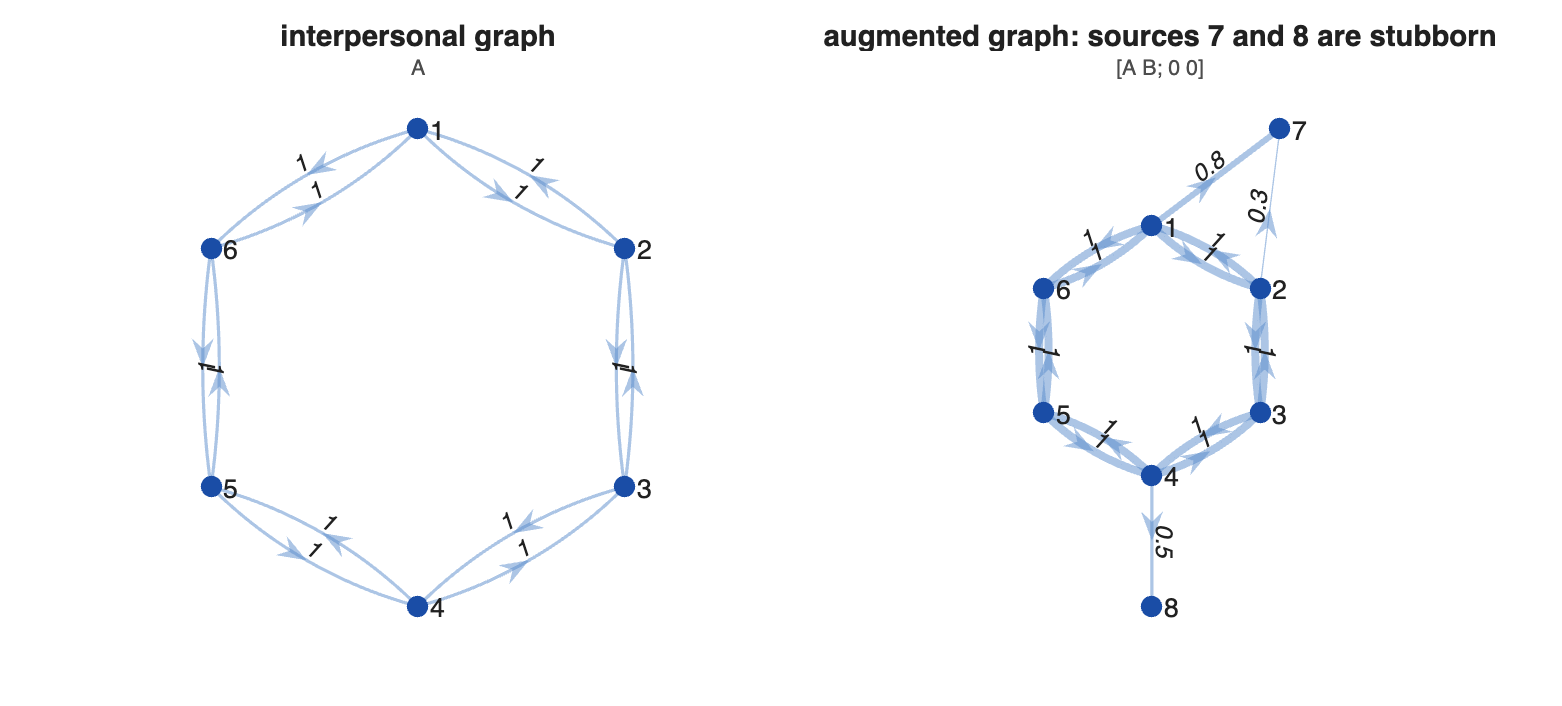

A = ring_graph(N) + ring_graph(N).';
B = zeros(N,2);
B(1,1) = 0.8;  B(2,1) = 0.3;  B(4,2) = 0.5;
sSrc = [-2; 4];

th   = pi/2 - (0:N-1).' * 2*pi/N;
ring = [cos(th), sin(th)];
pos  = [ring; 2.05*[cosd(60) sind(60)]; 2.05*[cosd(-90) sind(-90)]];

figure('Position',[0 0 1150 520]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
nexttile; plot_graph(A, [], 'Title','interpersonal graph', 'Subtitle','A');
nexttile; plot_graph([A B; zeros(2, N+2)], [], 'Layout', pos, ...
    'Title','augmented graph: sources 7 and 8 are stubborn', 'Subtitle','[A B; 0 0]');


B

B =     0.8000         0
    0.3000         0
         0         0
         0    0.5000
         0         0
         0         0


sSrc

sSrc =     -2
     4


gamma = sum(B, 2);
u     = zeros(N,1);
anch  = gamma > 0;
u(anch) = (B(anch,:) * sSrc) ./ gamma(anch);

disp(table((1:N).', gamma, u, anch, 'VariableNames', {'agent','gamma','u','prejudiced'}))

    agent    gamma    u     prejudiced
    _____    _____    __    __________

      1       0.8     -2      true    
      2       0.3     -2      true    
      3         0      0      false   
      4       0.5      4      true    
      5         0      0      false   
      6         0      0      false   




Xtay = sim_taylor(A, gamma, u, x0, t);
Xabl = sim_abelson([A B; zeros(2, N+2)], [x0; sSrc], t);

fprintf('max |M3.2 trajectory - augmented Abelson trajectory| = %.3e\n', ...
    max(max(abs(Xtay - Xabl(1:N,:)))));

max |M3.2 trajectory - augmented Abelson trajectory| = 2.220e-15


fprintf('the two virtual agents moved by                        %.3e\n', ...
    max(max(abs(Xabl(N+1:end,:) - sSrc))));

the two virtual agents moved by                        0.000e+00


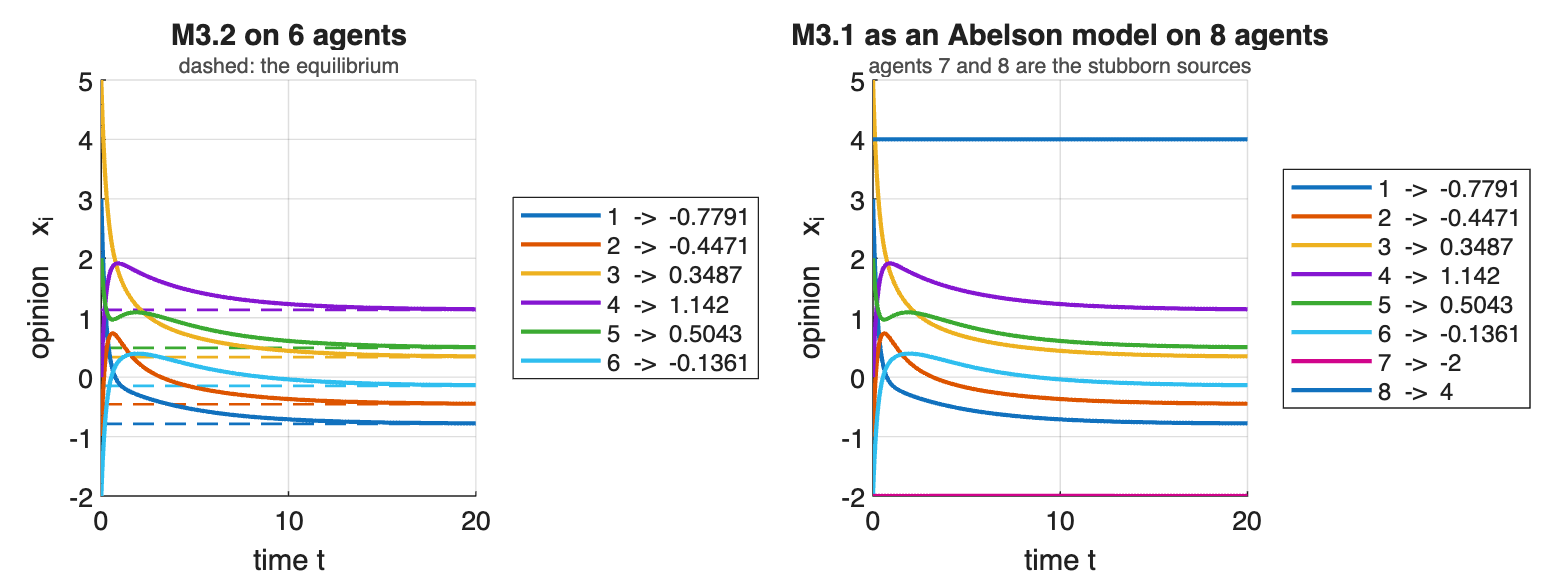

figure('Position',[0 0 1150 430]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
nexttile;
plot_opinions(Xtay, t, 'Limit', taylor_equilibrium(A, gamma, u), ...
    'Title','M3.2 on 6 agents', 'Subtitle','dashed: the equilibrium');
nexttile;
plot_opinions(Xabl, t, 'Title','M3.1 as an Abelson model on 8 agents', ...
    'Subtitle','agents 7 and 8 are the stubborn sources');

The equivalence holds spectrally too. The augmented Laplacian is block upper triangular with L + Gamma in its leading block, so its spectrum is that of the reduced system together with one zero per source. Moving the sources out of the state is what removes those zeros.

Laug = laplacian([A B; zeros(2, N+2)]);
fprintf('leading block of L_aug equals L + Gamma : %.2e\n', ...
    norm(Laug(1:N,1:N) - (laplacian(A) + diag(gamma)), Inf));

leading block of L_aug equals L + Gamma : 0.00e+00


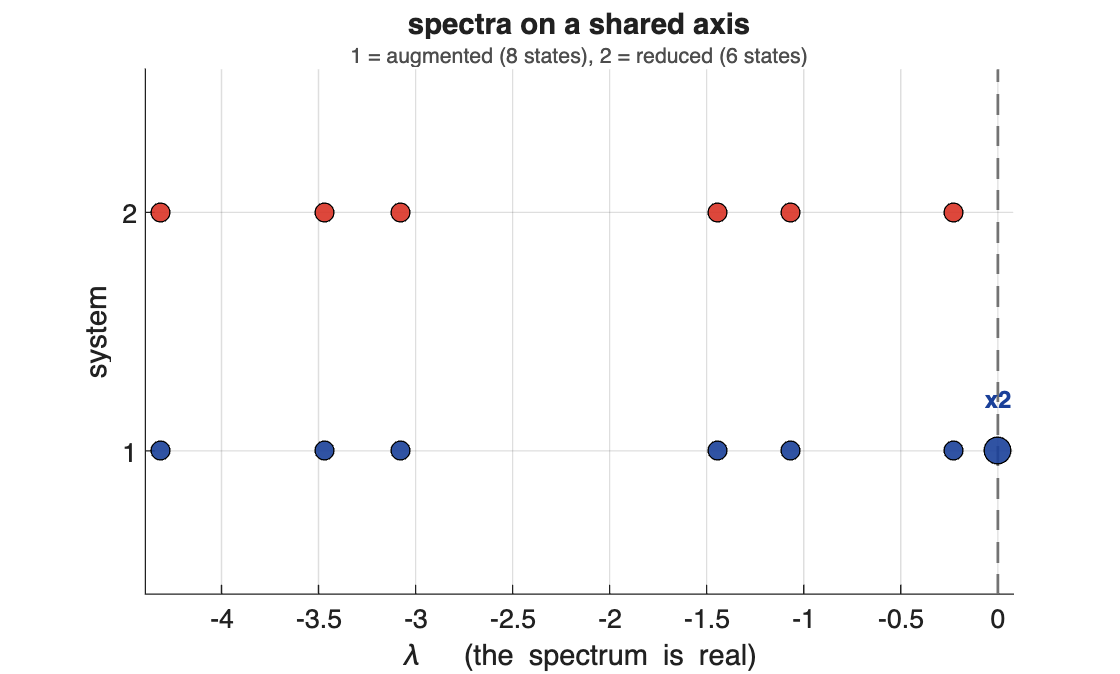


figure;
plot_spectrum_family({-Laug, -(laplacian(A)+diag(gamma))}, [1 2], 'continuous', ...
    'Rows','index', 'Label','system', 'Title','spectra on a shared axis', ...
    'Subtitle','1 = augmented (8 states), 2 = reduced (6 states)');


stability_summary({-Laug, -(laplacian(A)+diag(gamma))}, ...
    {'M3.1 augmented','M3.2 reduced'}, 'continuous')

ans = 2×4 table
         system         abscissa    margin     asymptotically_stable
    ________________    ________    _______    _____________________

    "M3.1 augmented"           0          0            false        
    "M3.2 reduced"      -0.23008    0.23008            true         


## 3.4.2 What the prejudice adds

Writing gamma = alpha * gamma_0 and turning alpha interpolates between the two models: at alpha = 0 the system is exactly Abelson, and as alpha grows each prejudiced agent is pulled harder towards its own u_i.

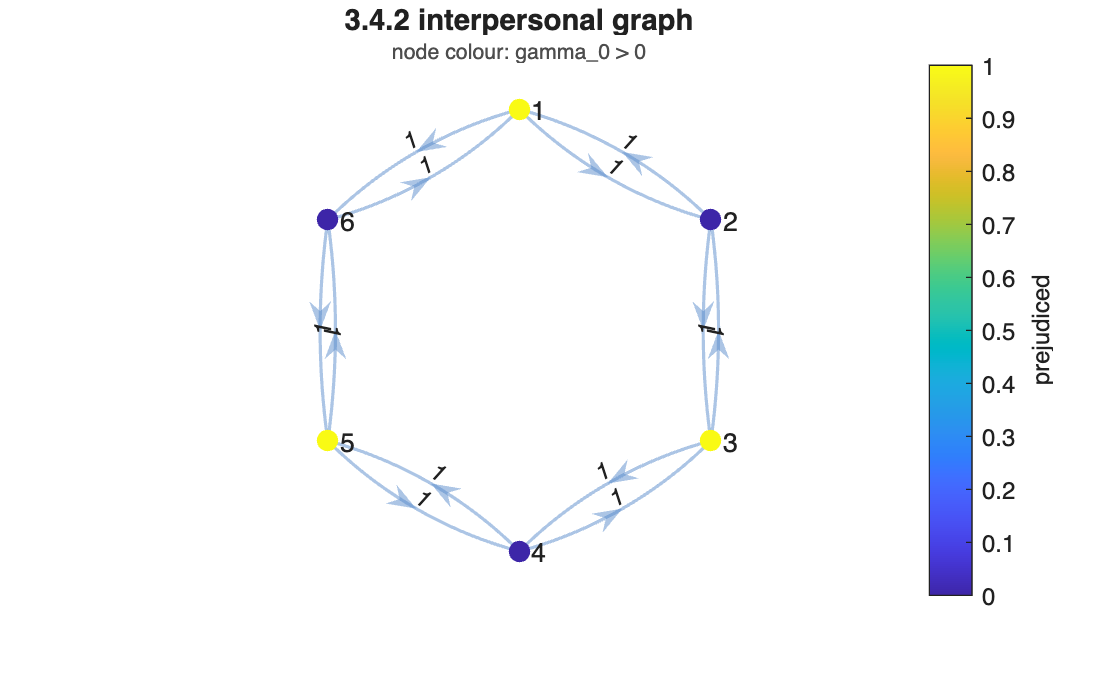

A  = ring_graph(N) + ring_graph(N).';
g0 = [1; 0; 1; 0; 1; 0];
u  = [-4; 0; 0; 0; 4; 0];
span = max(u(g0>0)) - min(u(g0>0));

figure;
plot_graph(A, [], 'NodeValue', g0, 'NodeName','prejudiced', ...
    'Title','3.4.2 interpersonal graph', 'Subtitle','node colour: gamma_0 > 0')

Trajectories on a logarithmic time axis, so both timescales are visible: the fast averaging set by L, and the slow pull towards the prejudices set by Gamma.

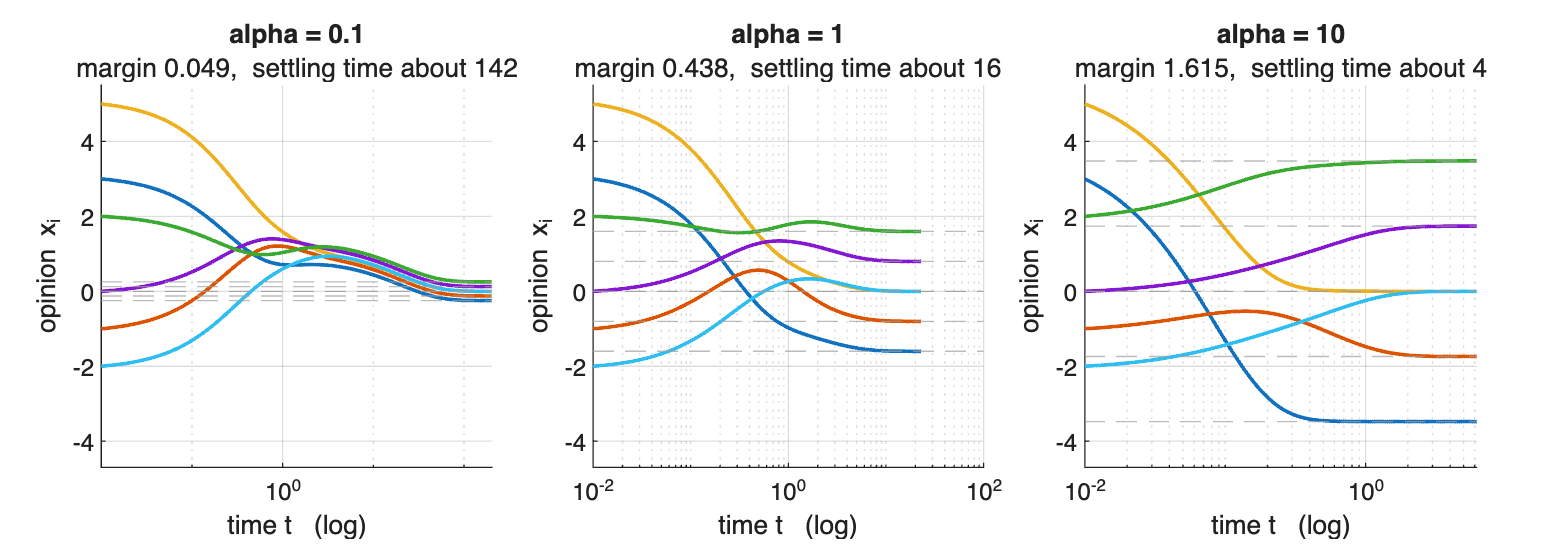

figure('Position',[0 0 1250 440]);
tiledlayout(1, 3, 'TileSpacing','compact', 'Padding','compact');
for a = [0.1 1 10]
    g   = a * g0;
    mar = -max(real(eig(-(laplacian(A) + diag(g)))));
    tt  = logspace(-2, log10(10/mar), 600);
    X   = sim_taylor(A, g, u, x0, tt);
    xs  = taylor_equilibrium(A, g, u);

    nexttile; hold on
    plot(tt, X.', 'LineWidth', 1.4);
    for i = 1:N, yline(xs(i), '--', 'Color', [.62 .62 .62]); end
    set(gca, 'XScale', 'log'); grid on; ylim([-4.7 5.5]);
    xlabel('time t   (log)'); ylabel('opinion x_i');
    title(sprintf('alpha = %g', a), 'FontWeight','bold');
    subtitle(sprintf('margin %.3f,  settling time about %.0f', mar, 7/mar));
end

The two quantities that summarise the sweep are the stability margin and the disagreement, and they are best read against each other.

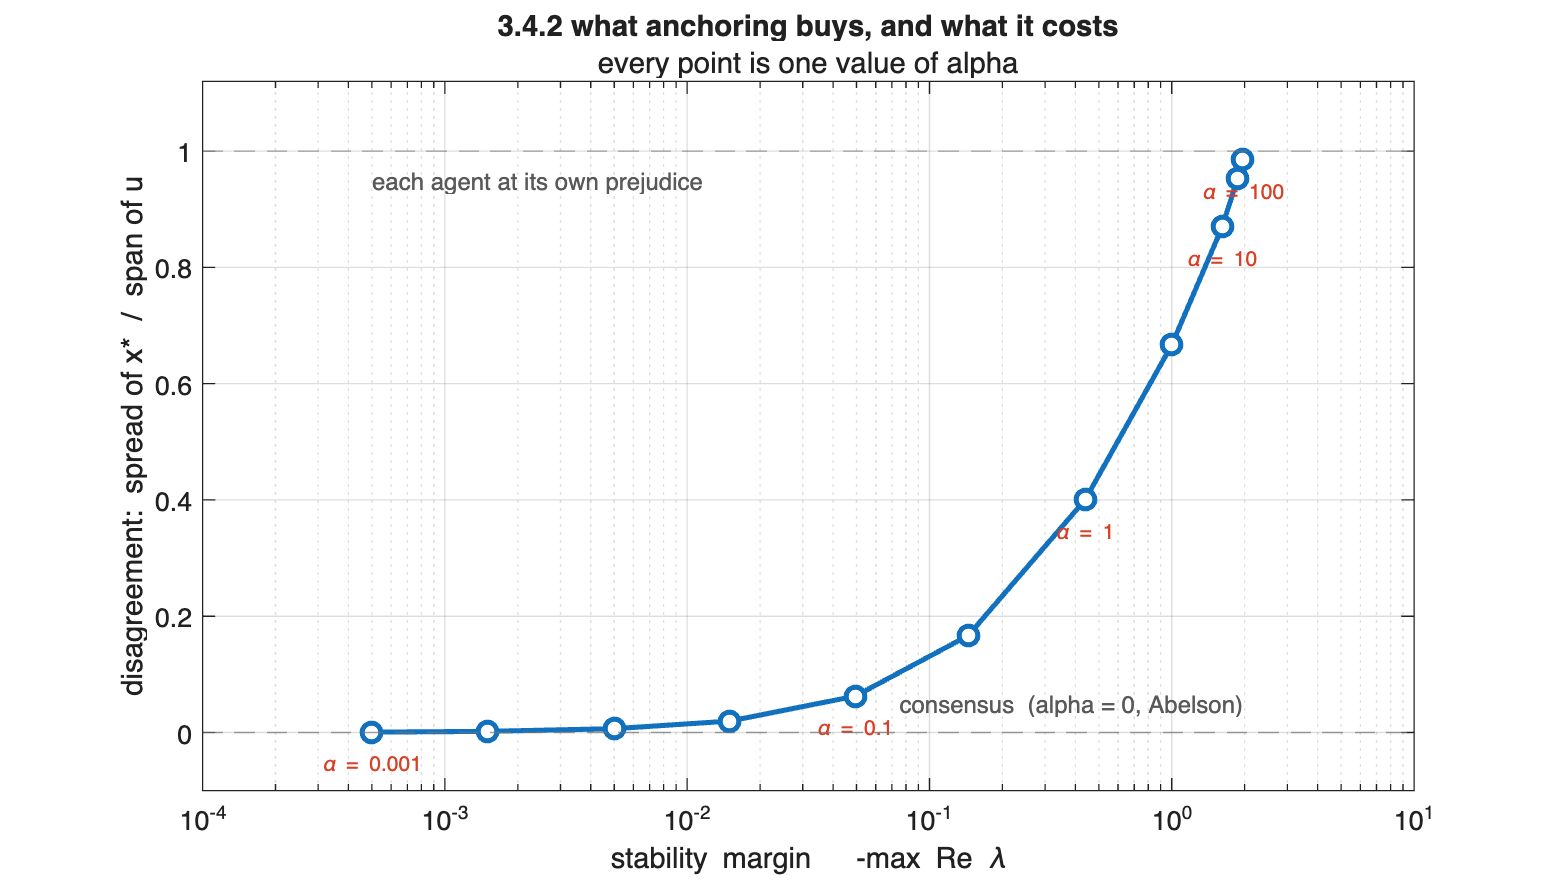

alphas = [1e-3 3e-3 1e-2 3e-2 0.1 0.3 1 3 10 30 100];
margin = zeros(size(alphas));
disagr = zeros(size(alphas));
for k = 1:numel(alphas)
    g = alphas(k) * g0;
    margin(k) = -max(real(eig(-(laplacian(A) + diag(g)))));
    xs        = taylor_equilibrium(A, g, u);
    disagr(k) = (max(xs) - min(xs)) / span;
end

figure('Position',[0 0 880 500]);
semilogx(margin, disagr, 'o-', 'LineWidth', 1.9, 'MarkerFaceColor','w', 'MarkerSize', 7);
hold on; grid on
yline(0, '--', 'Color', [.45 .45 .45]);
yline(1, '--', 'Color', [.45 .45 .45]);
text(margin(end), 0.05, 'consensus  (alpha = 0, Abelson)', 'FontSize', 9, ...
     'Color', [.35 .35 .35], 'HorizontalAlignment','right');
text(margin(1), 0.95, 'each agent at its own prejudice', 'FontSize', 9, ...
     'Color', [.35 .35 .35], 'HorizontalAlignment','left');
for k = [1 5 7 9 11]
    text(margin(k), disagr(k) - 0.055, ['\alpha = ' num2str(alphas(k))], ...
        'FontSize', 8, 'HorizontalAlignment','center', 'Color', [0.85 0.25 0.15]);
end
ylim([-0.1 1.12]);
xlabel('stability margin   -max Re \lambda');
ylabel('disagreement:  spread of x*  /  span of u');
title('3.4.2 what anchoring buys, and what it costs', 'FontWeight','bold');
subtitle('every point is one value of alpha');


fprintf('  alpha    margin    settling time   margin x time\n');

  alpha    margin    settling time   margin x time


for a = [0.1 0.3 1 3 10]
    g   = a * g0;
    mar = -max(real(eig(-(laplacian(A) + diag(g)))));
    xs  = taylor_equilibrium(A, g, u);
    tt  = linspace(0, 30/mar, 4000);
    X   = sim_taylor(A, g, u, x0, tt);
    j   = find(max(abs(X - xs), [], 1) < 1e-3, 1);
    fprintf('  %-7g  %.4f    %9.2f       %.2f\n', a, mar, tt(j), mar*tt(j));
end

  0.1      0.0494       142.82       7.05
  0.3      0.1444        48.68       7.03
  1        0.4384        15.76       6.91
  3        1.0000         6.33       6.33
  10       1.6148         4.06       6.56


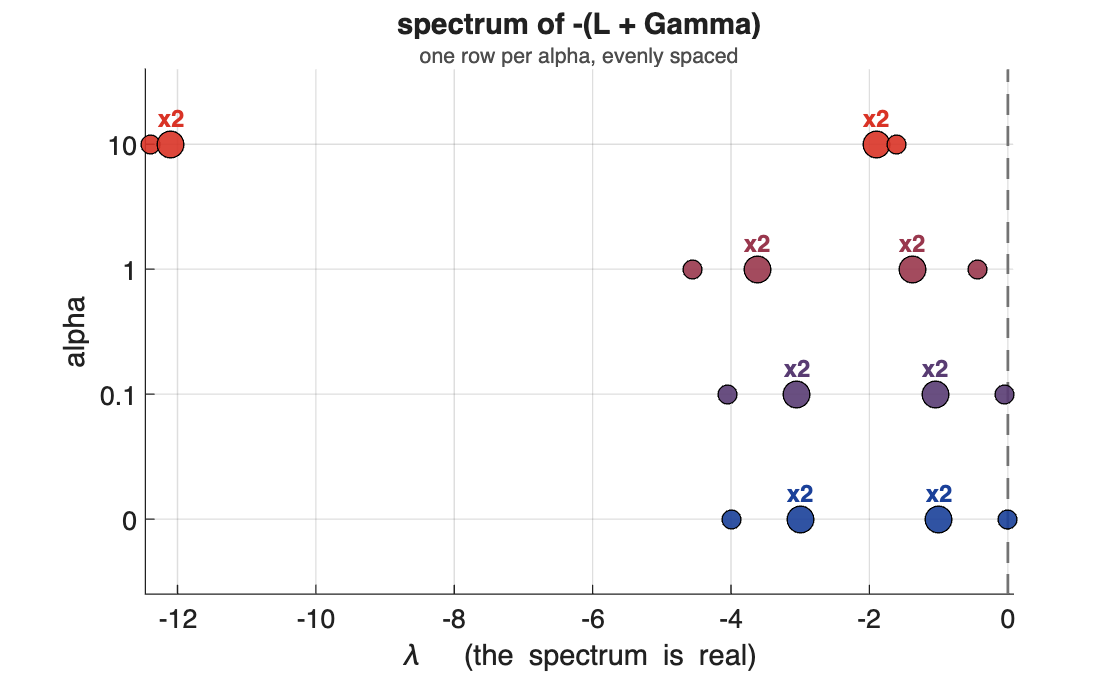

alphaShow = [0 0.1 1 10];
Ms = arrayfun(@(a) -(laplacian(A) + diag(a*g0)), alphaShow, 'UniformOutput', false);

figure;
plot_spectrum_family(Ms, alphaShow, 'continuous', 'Rows','index', 'Label','alpha', ...
    'Title','spectrum of -(L + Gamma)', 'Subtitle','one row per alpha, evenly spaced');


stability_summary(Ms, compose('alpha = %g', alphaShow), 'continuous')

ans = 4×4 table
       system        abscissa      margin     asymptotically_stable
    _____________    _________    ________    _____________________

    "alpha = 0"              0           0            false        
    "alpha = 0.1"    -0.049375    0.049375            true         
    "alpha = 1"       -0.43845     0.43845            true         
    "alpha = 10"       -1.6148      1.6148            true         


For every alpha > 0 the equilibrium is unique and independent of x(0); at alpha = 0 exactly the Abelson limit is px(0) and does depend on it.

fprintf('Abelson limit  (alpha = 0)      : %+.4f   (depends on x(0))\n', ...
    laplacian_power(A).' * x0);

Abelson limit  (alpha = 0)      : +1.1667   (depends on x(0))


fprintf('weighted average of prejudices  : %+.4f\n', ...
    (laplacian_power(A).' * (g0.*u)) / (laplacian_power(A).' * g0));

weighted average of prejudices  : -0.0000


for a = [1e-3 1e-2 1e-1]
    xs = taylor_equilibrium(A, a*g0, u);
    fprintf('Taylor equilibrium, alpha = %-6g: mean %+.4f, spread %.4f\n', ...
        a, mean(xs), max(xs)-min(xs));
end

Taylor equilibrium, alpha = 0.001 : mean +0.0000, spread 0.0053
Taylor equilibrium, alpha = 0.01  : mean -0.0000, spread 0.0530
Taylor equilibrium, alpha = 0.1   : mean +0.0000, spread 0.5000


## 3.4.3 Structural decomposition: M3.3.1 and M3.3.2

Unlike the two earlier models, the agents here are not one homogeneous population. Section 3.2 splits them into P-dependent agents, which some prejudice reaches, and P-independent ones, which none does. This example follows that split from the graph to the matrices to the spectrum to the observed behaviour.

### Step 1  -  the network and the two agent classes

Six agents. Agent 1 is prejudiced; agents 2, 4, 6 form a group that listens only to itself. The layout puts the P-dependent agents in the left column and the P-independent ones in the right, so the one-way coupling between the classes is visible: arrows cross from right to left and never back.

N  = 6;
Ad = zeros(N);
Ad(3,1) = 1;  Ad(5,3) = 1;              % inside the PD group
Ad(3,4) = 1;  Ad(5,6) = 1;              % PD agents also listen to PI agents
Ad(2,4) = 1;  Ad(4,2) = 1;              % inside the PI group
Ad(4,6) = 1;  Ad(6,4) = 1;

gd = [1.5; 0; 0; 0; 0; 0];              % only agent 1 is prejudiced
ud = [6;   0; 0; 0; 0; 0];

pd = prejudice_reach(Ad, gd > 0);
p1 = find(pd).';   p2 = find(~pd).';   perm = [p1 p2];   r = numel(p1);

fprintf('prejudiced agents  : %s\n', mat2str(find(gd > 0).'));

prejudiced agents  : 1


fprintf('P-dependent   (PD) : %s\n', mat2str(p1));

P-dependent   (PD) : [1 3 5]


fprintf('P-independent (PI) : %s\n', mat2str(p2));

P-independent (PI) : [2 4 6]


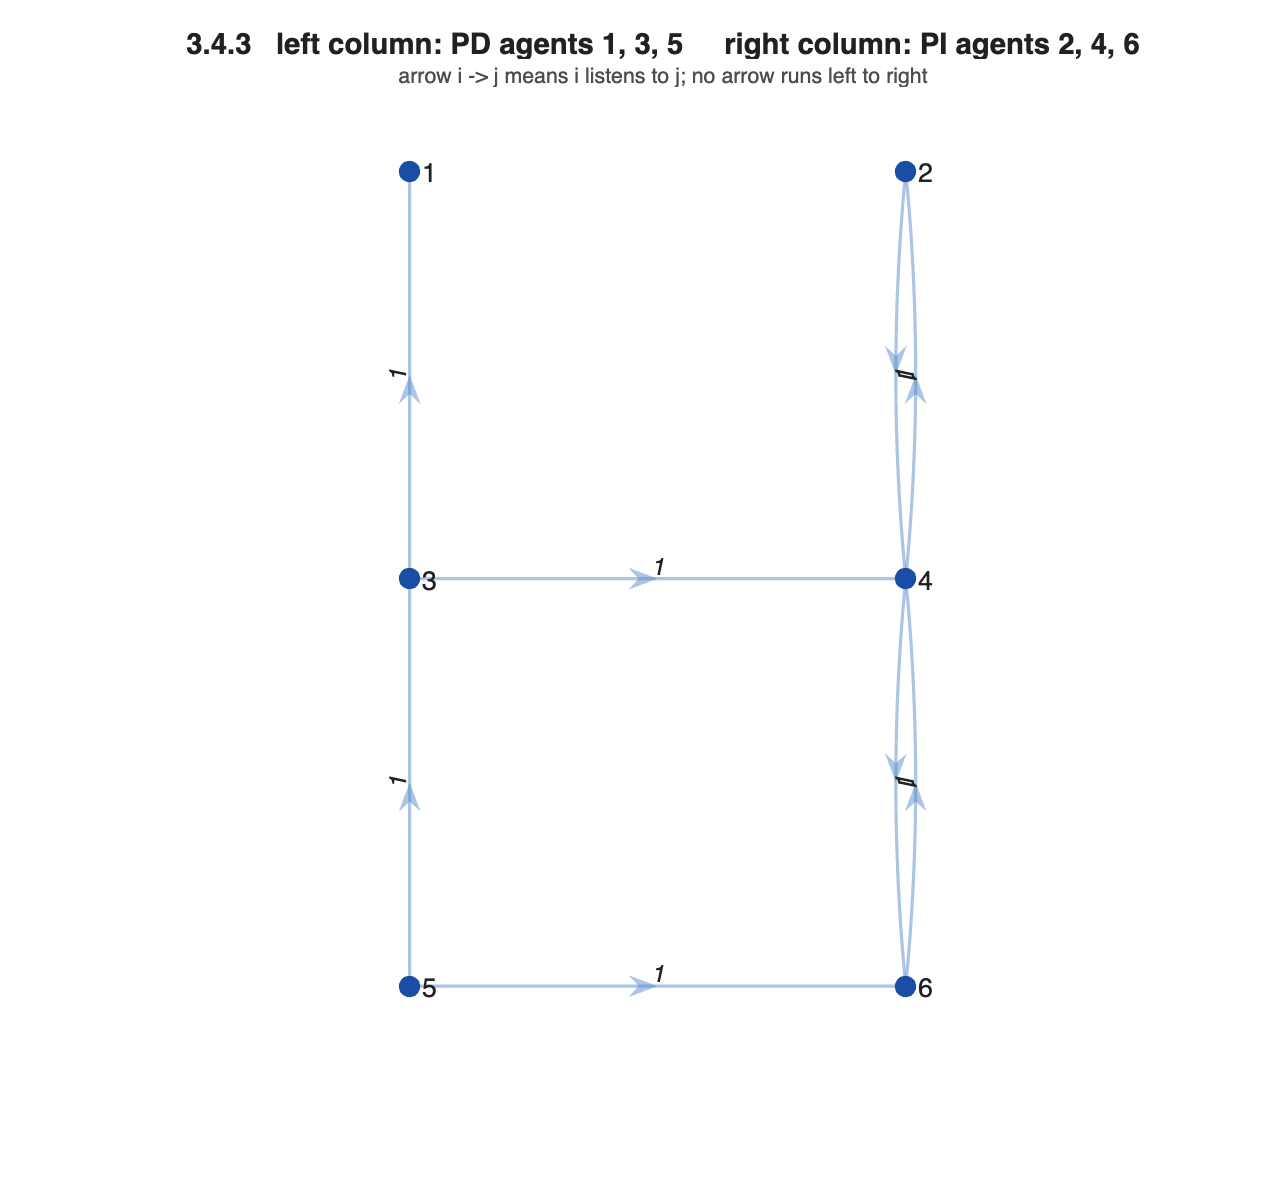


pos = zeros(N,2);
pos(p1,:) = [zeros(r,1),         1.15*(r:-1:1).'];        % PD column, left
pos(p2,:) = [1.4*ones(N-r,1),    1.15*(N-r:-1:1).'];      % PI column, right

figure('Position',[0 0 640 600]);
plot_graph(Ad, [], 'Layout', pos, ...
    'Title','3.4.3   left column: PD agents 1, 3, 5     right column: PI agents 2, 4, 6', ...
    'Subtitle','arrow i -> j means i listens to j; no arrow runs left to right')

### Step 2  -  the same structure in the system matrix

Reordering the agents so the PD ones come first, as the theory does, puts the matrix in block form. The lower-left block is exactly zero: a P-independent agent listening to a P-dependent one would itself be reached by the prejudice, so that block cannot be anything else.

L = laplacian(Ad);  G = diag(gd);
S = -(L + G);

fprintf('agents in the order used by the theory: %s\n\n', mat2str(perm));

agents in the order used by the theory: [1 3 5 2 4 6]



Sblocks = S(perm, perm)

Sblocks =    -1.5000         0         0         0         0         0
    1.0000   -2.0000         0         0    1.0000         0
         0    1.0000   -2.0000         0         0    1.0000
         0         0         0   -1.0000    1.0000         0
         0         0         0    1.0000   -2.0000    1.0000
         0         0         0         0    1.0000   -1.0000



L11 = L(p1,p1);  L12 = L(p1,p2);  L22 = L(p2,p2);  G11 = G(p1,p1);

fprintf('\nthe four blocks:\n');


the four blocks:


disp('  -(L11 + Gamma11)   the PD block, model M3.3.1');  disp(-(L11+G11));

  -(L11 + Gamma11)   the PD block, model M3.3.1
   -1.5000         0         0
    1.0000   -2.0000         0
         0    1.0000   -2.0000



disp('  -L12               how the PI agents drive the PD ones');  disp(-L12);

  -L12               how the PI agents drive the PD ones
     0     0     0
     0     1     0
     0     0     1



disp('  zero               the PI agents are not driven by anyone');  disp(zeros(N-r,r));

  zero               the PI agents are not driven by anyone
     0     0     0
     0     0     0
     0     0     0



disp('  -L22               the PI block, model M3.3.2');  disp(-L22);

  -L22               the PI block, model M3.3.2
    -1     1     0
     1    -2     1
     0     1    -1



The two blocks are the two models of the theory, and their row sums identify them. L22 is a genuine Laplacian, so M3.3.2 is a pure Abelson model on the P-independent agents alone. L11 is not: its row sums are minus those of L12, so adding Gamma11 leaves every row sum of L11 + Gamma11 strictly positive, which is what makes it a nonsingular M-matrix.

fprintf('row sums of L22            : %s   (Laplacian, so M3.3.2 is Abelson)\n', ...
    mat2str(round(sum(L22,2).', 12)));

row sums of L22            : [0 0 0]   (Laplacian, so M3.3.2 is Abelson)


fprintf('row sums of L11            : %s   (not a Laplacian)\n', ...
    mat2str(round(sum(L11,2).', 6)));

row sums of L11            : [0 1 1]   (not a Laplacian)


fprintf('||L11*1 + L12*1||          : %.2e\n', norm(sum(L11,2) + sum(L12,2), Inf));

||L11*1 + L12*1||          : 0.00e+00


fprintf('row sums of L11 + Gamma11  : %s   (all strictly positive)\n', ...
    mat2str(round(sum(L11+G11,2).', 6)));

row sums of L11 + Gamma11  : [1.5 1 1]   (all strictly positive)


### Step 3  -  which result applies, and what it predicts

Theorem 3.1 is stated for exactly this situation, r P-dependent and n - r P-independent agents, and asserts that the PD block alone is Hurwitz. Corollary 3.1 is an equivalence whose stability side needs every agent to be P-dependent; here r = 3 < 6, so the full system is NOT asymptotically stable and the corollary must not be applied to it.

What should therefore be expected: the PD block converges exponentially; the PI block is an Abelson model, which converges for any non-negative weights; so the whole state converges, but its limit is not forced to be unique, and nothing in either result promises consensus.

### Step 4  -  the spectrum, read through the decomposition

The matrix is block triangular, so every eigenvalue belongs to one block or the other.

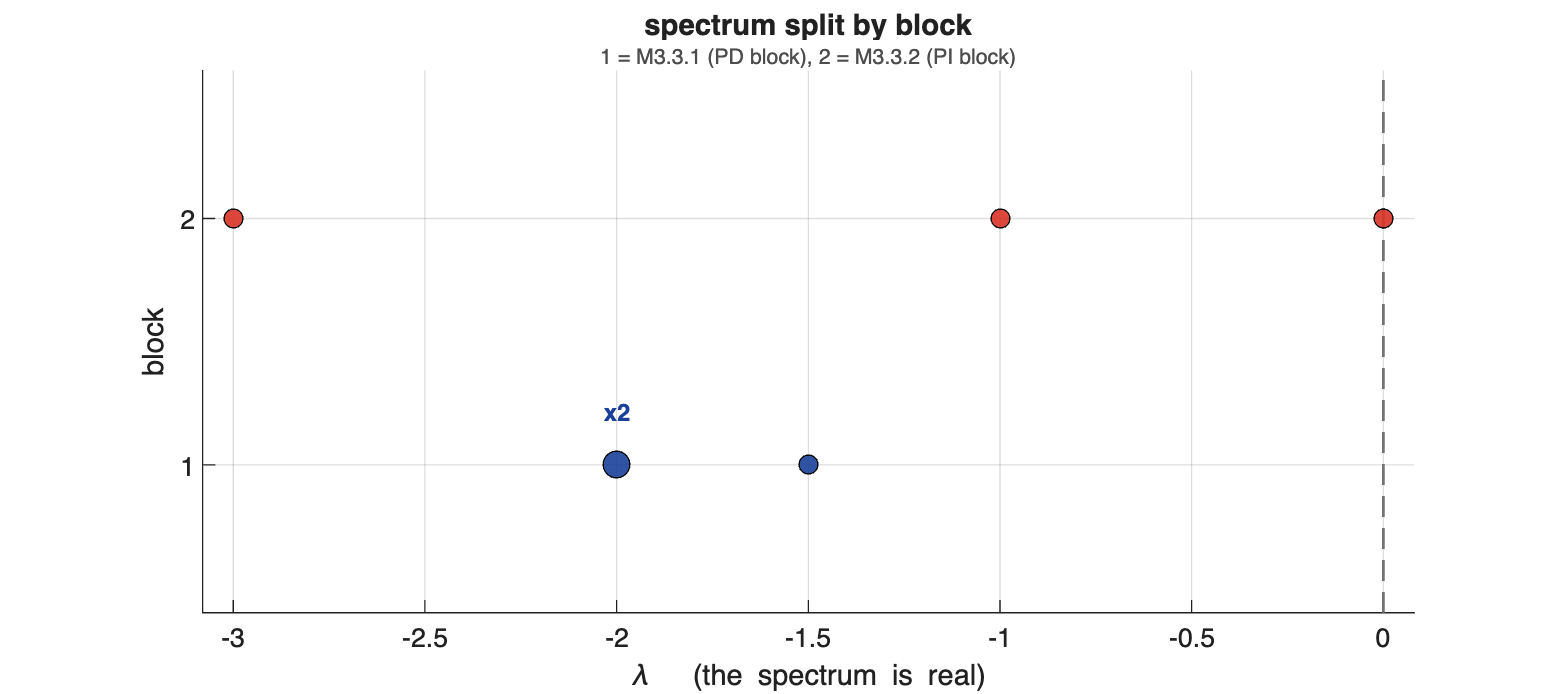

figure('Position',[0 0 900 400]);
plot_spectrum_family({-(L11+G11), -L22}, [1 2], 'continuous', 'Rows','index', ...
    'Label','block', 'Title','spectrum split by block', ...
    'Subtitle','1 = M3.3.1 (PD block), 2 = M3.3.2 (PI block)');


eFull  = sort(real(eig(S)), 'descend');
eSplit = sort([real(eig(-(L11+G11))); real(eig(-L22))], 'descend');
fprintf('spectrum of M3.3 equals the union of the two blocks : %.2e\n\n', ...
    max(abs(eFull - eSplit)));

spectrum of M3.3 equals the union of the two blocks : 8.88e-16




stability_summary({S, -(L11+G11), -L22}, ...
    {'full system  M3.3','PD block  M3.3.1','PI block  M3.3.2'}, 'continuous')

ans = 3×4 table
          system           abscissa    margin    asymptotically_stable
    ___________________    ________    ______    _____________________

    "full system  M3.3"         0         0              false        
    "PD block  M3.3.1"       -1.5       1.5              true         
    "PI block  M3.3.2"          0         0              false        


The eigenvalue at the origin sits in the PI block and nowhere else. It is the Laplacian zero of M3.3.2, and it is the only reason the full system fails to be asymptotically stable.

### Step 5  -  what the trajectories actually do

Convergence, asymptotic stability and consensus are three different properties, so they are tested separately rather than read off the picture. The test for asymptotic stability is to run the same model from two different initial conditions and compare the limits.

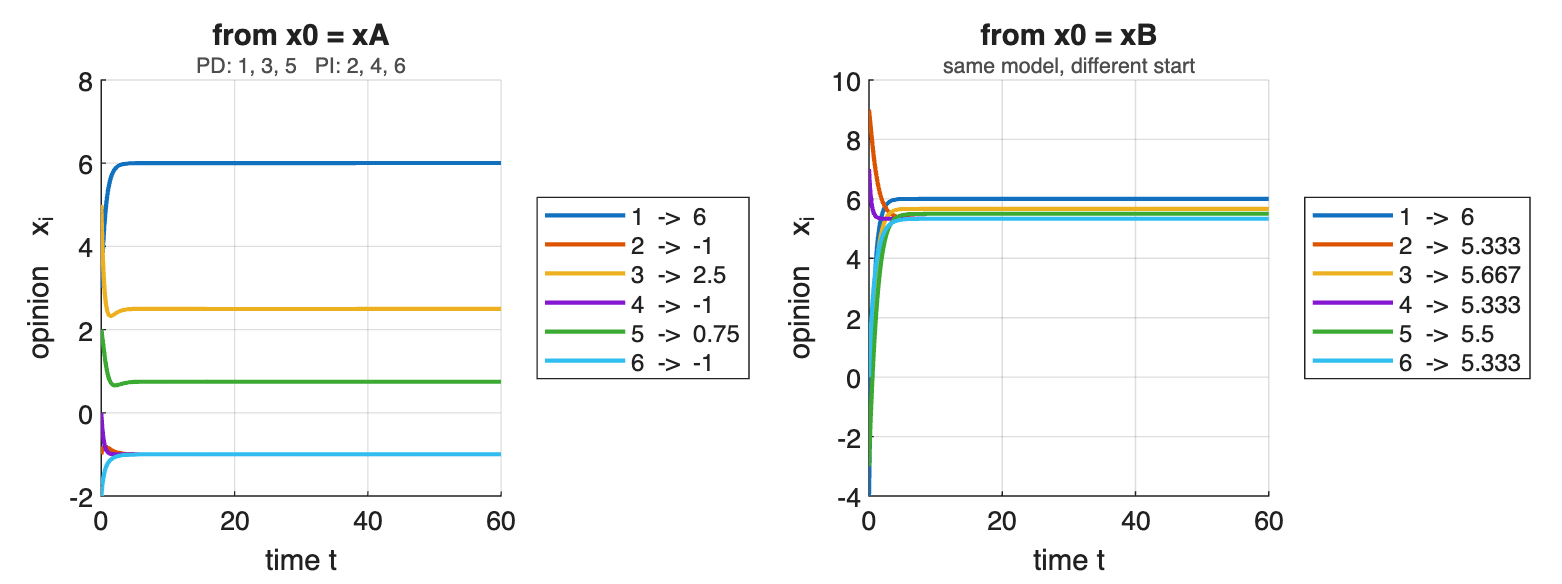

xA = [3; -1; 5; 0; 2; -2];
xB = [-4; 9; 1; 7; -3; 0];
tt = linspace(0, 60, 800);

XA = sim_taylor(Ad, gd, ud, xA, tt);
XB = sim_taylor(Ad, gd, ud, xB, tt);

figure('Position',[0 0 1150 430]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
nexttile; plot_opinions(XA, tt, 'Title','from x0 = xA', 'Subtitle','PD: 1, 3, 5   PI: 2, 4, 6');
nexttile; plot_opinions(XB, tt, 'Title','from x0 = xB', 'Subtitle','same model, different start');


limit_report({XA, XB}, {'from xA','from xB'})

ans = 2×5 table
       run       converged    limit_spread    consensus    same_limit_as_first
    _________    _________    ____________    _________    ___________________

    "from xA"      true               7         false             true        
    "from xB"      true         0.66667         false             false       


Both runs converge and neither reaches consensus, and the two limits differ: the outcome still remembers where it started. That memory lives entirely in the P-independent block, which runs its own Abelson model and settles at the weighted average of its own initial values.

A22 = Ad(p2,p2);
fprintf('PI subgraph on agents %s is rooted : %d\n', mat2str(p2), graph_summary(A22).rooted);

PI subgraph on agents [2 4 6] is rooted : 1


fprintf('PI limit from xA : %s   Abelson prediction %.4f\n', ...
    mat2str(round(XA(p2,end).',4)), laplacian_power(A22).' * xA(p2));

PI limit from xA : [-1 -1 -1]   Abelson prediction -1.0000


fprintf('PI limit from xB : %s   Abelson prediction %.4f\n', ...
    mat2str(round(XB(p2,end).',4)), laplacian_power(A22).' * xB(p2));

PI limit from xB : [5.3333 5.3333 5.3333]   Abelson prediction 5.3333



M = (L11 + G11) \ [G11, -L12];
fprintf('\nTheorem 3.1:  M is %d-by-%d, row sums %s, min entry %.2e\n', size(M,1), size(M,2), ...
    mat2str(round(sum(M,2).', 10)), min(M(:)));


Theorem 3.1:  M is 3-by-6, row sums [1 1 1], min entry 0.00e+00


fprintf('predicted PD limit from xA : %s\n', mat2str(round((M*[ud(p1); XA(p2,end)]).', 4)));

predicted PD limit from xA : [6 2.5 0.75]


fprintf('simulated  PD limit from xA : %s\n', mat2str(round(XA(p1,end).', 4)));

simulated  PD limit from xA : [6 2.5 0.75]


### Step 6  -  removing the P-independent block

Adding one prejudice on agent 4 reaches the whole PI group, so r becomes n. Corollary 3.1 now applies, and the change is visible in all three properties at once.

gd2 = gd;  gd2(4) = 0.7;
fprintf('after a prejudice on agent 4, PD = %s\n\n', mat2str(find(prejudice_reach(Ad, gd2>0)).'));

after a prejudice on agent 4, PD = [1 2 3 4 5 6]



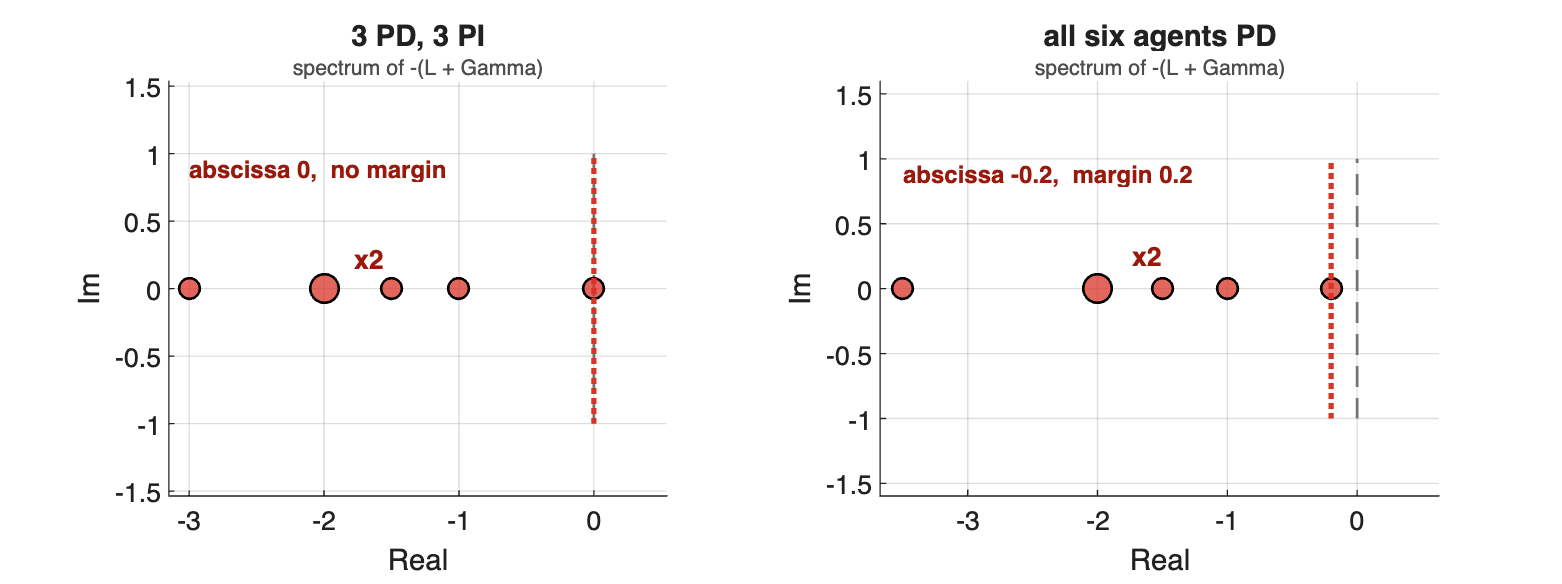


t6 = linspace(0, 150, 800);          % margin 0.2, so run long enough to resolve the limit
YA = sim_taylor(Ad, gd2, ud, xA, t6);
YB = sim_taylor(Ad, gd2, ud, xB, t6);

figure('Position',[0 0 1150 430]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
nexttile;
plot_eigenvalues(-(L + diag(gd)),  'continuous', 'Abscissa', true, ...
    'Title','3 PD, 3 PI', 'Subtitle','spectrum of -(L + Gamma)');
nexttile;
plot_eigenvalues(-(L + diag(gd2)), 'continuous', 'Abscissa', true, ...
    'Title','all six agents PD', 'Subtitle','spectrum of -(L + Gamma)');


stability_summary({-(L + diag(gd)), -(L + diag(gd2))}, {'3 PD, 3 PI','all PD'}, 'continuous')

ans = 2×4 table
       system       abscissa    margin    asymptotically_stable
    ____________    ________    ______    _____________________

    "3 PD, 3 PI"         0         0              false        
    "all PD"          -0.2       0.2              true         


limit_report({YA, YB}, {'all PD, from xA','all PD, from xB'})

ans = 2×5 table
           run           converged    limit_spread    consensus    same_limit_as_first
    _________________    _________    ____________    _________    ___________________

    "all PD, from xA"      true            6            false             true        
    "all PD, from xB"      true            6            false             true        


The two limits now agree to rounding error: that is what asymptotic stability buys, and it is a statement about forgetting the initial condition, not about agreement. The limit spread is still far from zero, so the agents converge to a persistent disagreement in both cases. Stability, convergence and consensus are three separate questions, and here the answers are yes, yes and no.

## 3.4.4 Containment control

Theorem 3.2 states three equivalent conditions, the last of them geometric: the agents reach the convex hull of the leaders, for any leader positions and any initial conditions, exactly when every agent is P-dependent. The scenario below is the multidimensional Taylor model of section 3.3: six mobile agents, three static leaders, and positions in the plane. Each coordinate obeys the same scalar model, so the two coordinates are simulated separately.

Two configurations are compared. They share the same follower network and differ only in whether any follower can sense a leader, which is the structural distinction of section 3.2 applied to this problem: with sensing, every follower is P-dependent; without it, Gamma = 0, no follower is P-dependent, and the followers reduce to a pure Abelson system among themselves.

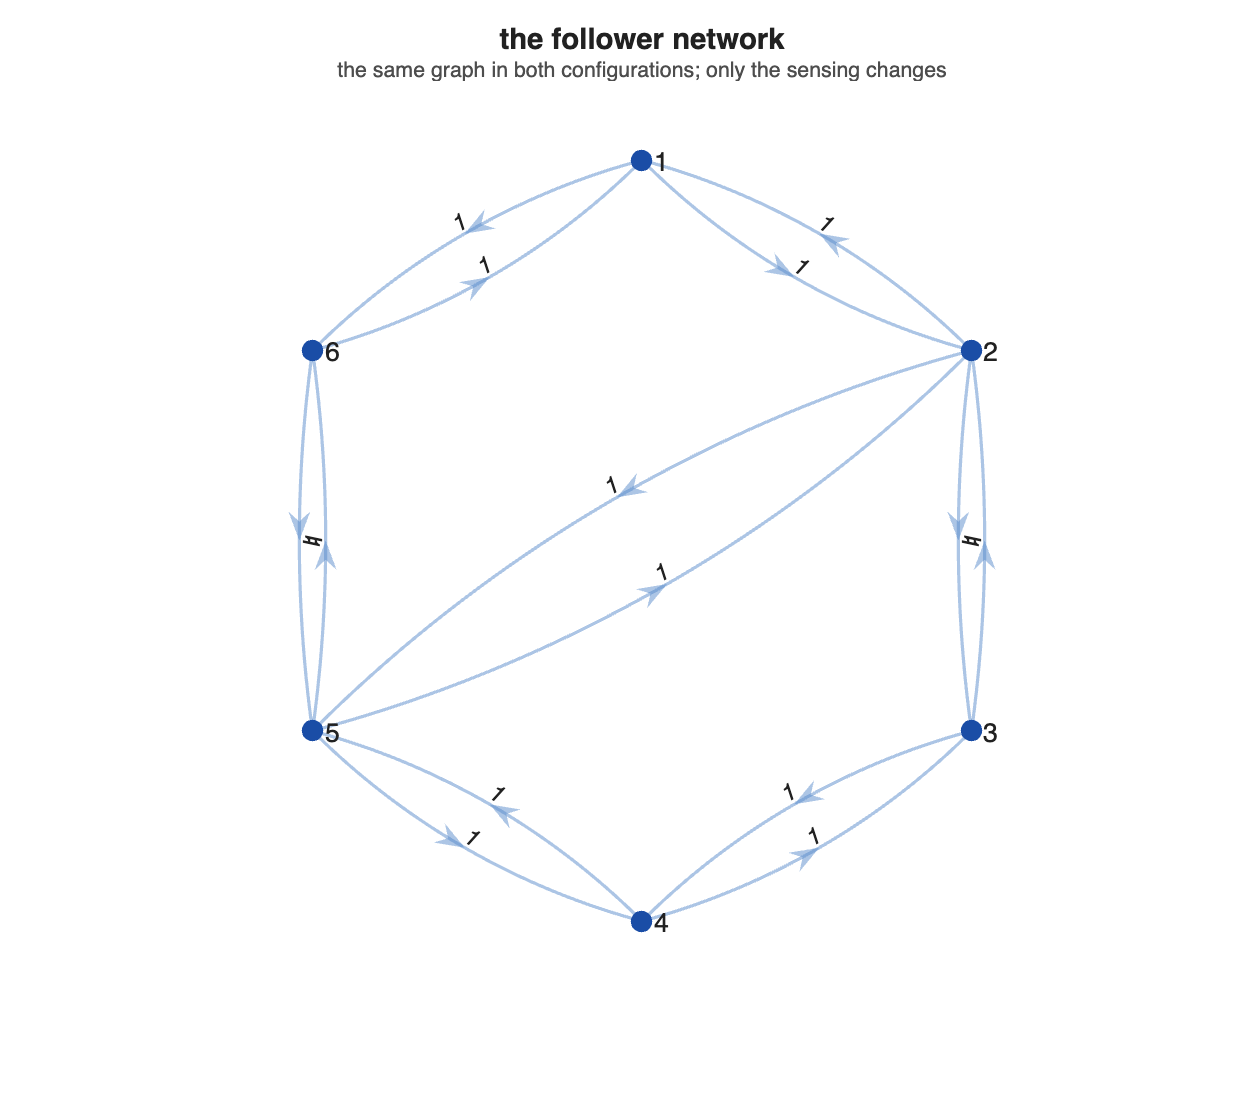

S  = [0 0; 6 0; 4 5];                       % three static leaders
X0 = [-3 4; -2 -3; 8 -2; 9 4; 2 8; 5 -4];   % initial follower positions

Af = zeros(N); ef = [1 2;2 3;3 4;4 5;5 6;6 1;2 5];
for e = ef.', Af(e(1),e(2)) = 1; Af(e(2),e(1)) = 1; end

Bpd = zeros(N,3);  Bpd(1,1) = 1;  Bpd(3,2) = 1;  Bpd(5,3) = 1;   % 1, 3, 5 sense a leader
Bpi = zeros(N,3);                                                % nobody senses a leader

cases = {'all followers PD', Bpd; 'all followers PI', Bpi};

figure('Position',[0 0 620 560]);
plot_graph(Af, [], 'Title','the follower network', ...
    'Subtitle','the same graph in both configurations; only the sensing changes')


disp(table((1:N).', sum(Bpd,2), prejudice_reach(Af, sum(Bpd,2) > 0), ...
                    sum(Bpi,2), prejudice_reach(Af, sum(Bpi,2) > 0), ...
    'VariableNames', {'follower','senses_leader_PD','PD_case','senses_leader_PI','PI_case'}))

    follower    senses_leader_PD    PD_case    senses_leader_PI    PI_case
    ________    ________________    _______    ________________    _______

       1               1             true             0             false 
       2               0             true             0             false 
       3               1             true             0             false 
       4               0             true             0             false 
       5               1             true             0             false 
       6               0             true             0             false 



The containment objective is that every follower ends inside conv(S), the triangle spanned by the leaders. The quantity tracked over time is the distance from a follower to that triangle, which is zero once the follower is inside it: containment is achieved when every curve reaches zero and stays there.

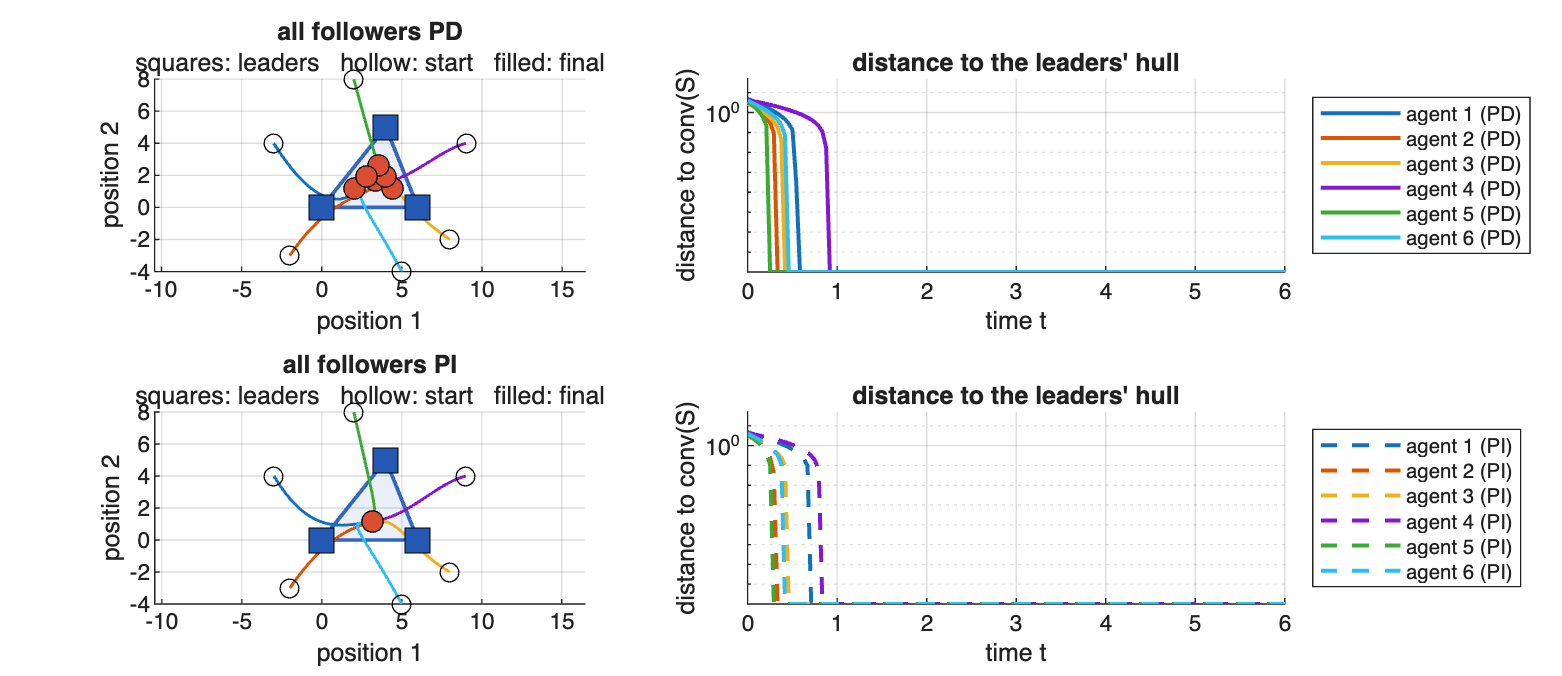

tc   = linspace(0, 25, 600);
hull = convhull(S(:,1), S(:,2));
tag  = {'PI','PD'};

figure('Position',[0 0 1250 540]);
tiledlayout(2, 2, 'TileSpacing','compact', 'Padding','compact');

for k = 1:2
    Bk  = cases{k,2};
    g   = sum(Bk, 2);
    U   = zeros(N,2);  nz = g > 0;
    if any(nz), U(nz,:) = (Bk(nz,:) * S) ./ g(nz); end
    pdk = prejudice_reach(Af, g > 0);

    P = zeros(N, numel(tc), 2);
    for c = 1:2, P(:,:,c) = sim_taylor(Af, g, U(:,c), X0(:,c), tc); end

    nexttile; hold on
    fill(S(hull,1), S(hull,2), [0.20 0.40 0.75], 'FaceAlpha', 0.10, ...
         'EdgeColor', [0.20 0.40 0.75], 'LineWidth', 1.4);
    plot(P(:,:,1).', P(:,:,2).', 'LineWidth', 1.1);
    plot(X0(:,1), X0(:,2), 'ko', 'MarkerSize', 7);
    plot(P(:,end,1), P(:,end,2), 'ko', 'MarkerFaceColor', [0.85 0.30 0.20], 'MarkerSize', 8);
    plot(S(:,1), S(:,2), 'ks', 'MarkerFaceColor', [0.15 0.35 0.70], 'MarkerSize', 12);
    axis equal; grid on; xlabel('position 1'); ylabel('position 2');
    title(cases{k,1}, 'FontWeight','bold');
    subtitle('squares: leaders   hollow: start   filled: final');

    dist = zeros(N, numel(tc));
    for j = 1:numel(tc)
        dist(:,j) = containment_distance([P(:,j,1), P(:,j,2)], S);
    end
    nexttile; hold on
    for a = 1:N
        if pdk(a), st = '-'; else, st = '--'; end
        plot(tc, max(dist(a,:), 1e-8), st, 'LineWidth', 1.5, ...
             'DisplayName', sprintf('agent %d (%s)', a, tag{1 + pdk(a)}));
    end
    set(gca,'YScale','log'); grid on; legend('Location','eastoutside');
    xlabel('time t'); ylabel('distance to conv(S)');
    ylim([1e-8 50]); xlim([0 6]);
    title('distance to the leaders'' hull', 'FontWeight','bold');
end

Both configurations appear to reach the hull, which is the point at which the structure has to be examined rather than the picture. The matrix that governs the follower dynamics is the same -(L + Gamma) used throughout the chapter, built from the follower graph and from the sensing: L is identical in the two configurations, so Gamma is the only difference between them.

L = laplacian(Af);
GammaPD = diag(sum(Bpd,2))

GammaPD =      1     0     0     0     0     0
     0     0     0     0     0     0
     0     0     1     0     0     0
     0     0     0     0     0     0
     0     0     0     0     1     0
     0     0     0     0     0     0


GammaPI = diag(sum(Bpi,2))

GammaPI =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0



Mpd = -(L + GammaPD);
Mpi = -(L + GammaPI);

The spectra of these two matrices answer the structural question directly: what does sensing a leader do to the system? Both spectra are real, so they are drawn on one axis, one row per configuration, with each eigenvalue joined to its counterpart. Adding a non-negative Gamma can only move eigenvalues left, so the segments show how far each mode is pushed into the stable half-plane.

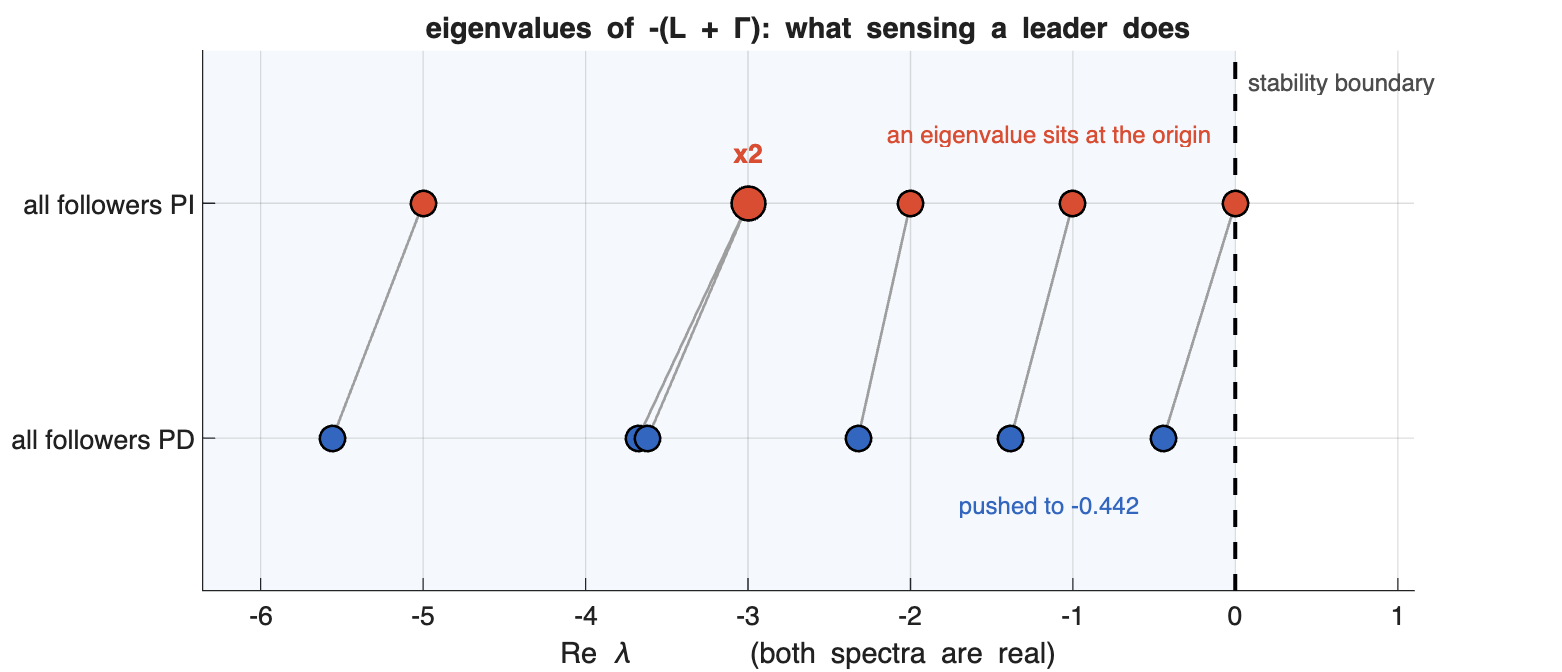

ePI = sort(real(eig(Mpi)), 'descend');
ePD = sort(real(eig(Mpd)), 'descend');
TPI = plot_eigenvalues(Mpi, 'continuous', 'Plot', false);
TPD = plot_eigenvalues(Mpd, 'continuous', 'Plot', false);

figure('Position',[0 0 1000 430]); hold on
xl = [min(ePD)-0.8, 1.1];
fill([xl(1) 0 0 xl(1)], [0.35 0.35 2.65 2.65], [0.20 0.45 0.75], ...
     'FaceAlpha', 0.05, 'EdgeColor','none');
plot([0 0], [0.35 2.65], 'k--', 'LineWidth', 1.5);
text(0.08, 2.52, 'stability boundary', 'FontSize', 9, 'Color', [.3 .3 .3]);

for k = 1:N
    plot([ePI(k) ePD(k)], [2 1], '-', 'Color', [0.62 0.62 0.62], 'LineWidth', 1);
end
scatter(TPI.Re, 2*ones(height(TPI),1), 90 + 70*(TPI.multiplicity-1), ...
    'MarkerFaceColor', [0.85 0.30 0.20], 'MarkerEdgeColor','k', 'LineWidth', 1);
scatter(TPD.Re, 1*ones(height(TPD),1), 90 + 70*(TPD.multiplicity-1), ...
    'MarkerFaceColor', [0.20 0.40 0.75], 'MarkerEdgeColor','k', 'LineWidth', 1);
for j = 1:height(TPI)
    if TPI.multiplicity(j) > 1
        text(TPI.Re(j), 2.22, sprintf('x%d', TPI.multiplicity(j)), ...
            'HorizontalAlignment','center', 'FontWeight','bold', 'Color', [0.85 0.30 0.20]);
    end
end
text(ePI(1) - 0.15, 2.30, 'an eigenvalue sits at the origin', 'FontSize', 9, ...
     'Color', [0.85 0.30 0.20], 'HorizontalAlignment','right');
text(ePD(1) - 0.15, 0.72, sprintf('pushed to %.3f', ePD(1)), 'FontSize', 9, ...
     'Color', [0.20 0.40 0.75], 'HorizontalAlignment','right');
grid on; xlim(xl); ylim([0.35 2.65]);
set(gca, 'YTick', [1 2], 'YTickLabel', {'all followers PD','all followers PI'});
xlabel('Re \lambda        (both spectra are real)');
title('eigenvalues of -(L + \Gamma): what sensing a leader does', 'FontWeight','bold');

Without sensing, the follower system is a Laplacian and carries an eigenvalue exactly at the origin: the consensus mode, along which the followers drift together with nothing to stop them. Sensing a leader pushes every eigenvalue left, that one to -0.442, and the system becomes Hurwitz. It also splits the repeated eigenvalue, since Gamma breaks the symmetry between otherwise interchangeable followers.

Whether the hull is actually reached follows from this. Theorem 3.2 asks for containment for ANY leader positions, so the two configurations are also run with the leaders translated by (20, 12), a rigid shift of the whole triangle. The table reports the spectral abscissa, the stability verdict, and how many followers finish inside the hull in each case.

Sfar = S + [20 12];
rows = cell(2,1);

for k = 1:2
    Bk = cases{k,2};  g = sum(Bk, 2);
    Mk = -(L + diag(g));
    inside = zeros(1,2);
    Sset = {S, Sfar};
    for q = 1:2
        Sn = Sset{q};
        U  = zeros(N,2);  nz = g > 0;
        if any(nz), U(nz,:) = (Bk(nz,:) * Sn) ./ g(nz); end
        P = zeros(N,2);
        for c = 1:2
            Xc = sim_taylor(Af, g, U(:,c), X0(:,c), [0 400]);
            P(:,c) = Xc(:,end);
        end
        hq = convhull(Sn(:,1), Sn(:,2));
        inside(q) = nnz(inpolygon(P(:,1), P(:,2), Sn(hq,1), Sn(hq,2)));
    end
    ab = max(real(eig(Mk)));
    if abs(ab) < 1e-9, ab = 0; end
    rows{k} = {string(cases{k,1}), ab, ab < 0, inside(1), inside(2)};
end

disp(cell2table(vertcat(rows{:}), 'VariableNames', ...
    {'configuration','abscissa','asymptotically_stable','inside_original','inside_moved'}))

      configuration       abscissa    asymptotically_stable    inside_original    inside_moved
    __________________    ________    _____________________    _______________    ____________

    "all followers PD"    -0.44239            true                    6                6      
    "all followers PI"           0            false                   6                0      



The P-dependent followers stay inside the hull wherever the leaders are put: that is containment, and it is the Hurwitz abscissa that delivers it. The P-independent followers finish in the same place whichever leaders are used, because with Gamma = 0 the leaders never enter their dynamics at all; their landing inside the original triangle was a coincidence of the initial condition, and moving the leaders exposes it. Note finally that the P-independent followers do reach consensus among themselves while failing containment, and the P-dependent ones achieve containment while never agreeing: containment and consensus are different objectives, and neither implies the other.